clear

## Analysis of a lumped parameter blood vessel network 

**ODE Model**

A simple representation of a blood vessel is a lumped parameter model. In this model, each vessel is represented as a zero-dimensional chamber, having a pressure, compliance, and resistance to flow. Under this representation, each vessel can be represented by an ordinary differential equation (ODE). For a vessel with time-varying pressure $p = p(t)$:

  
$$c \frac{dp}{dt} = \text{flow in} - \text{flow out}$$


The flow in depends on the state of the pressure in the upstream vessel. The flow out depends similarly on the downstream vessel. For example, if there is only one vessel upstream and downstream:

  
$$c \frac{dp}{dt} = \frac{p_{upstream} - p}{r_{in}} - \frac{p - p_{downstream}}{r_{out}}$$


Modeling a blood vessel network typically requires many equations of this form. Consider the system of 5 connected vessels shown below:

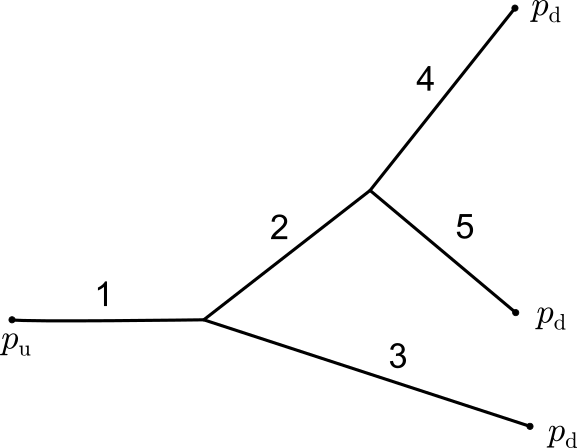

*Network of 5 connected vessels.*

To describe this system, you can define variables and constants for each vessel.

- $p_i = p_i(t)$: Pressure in the $i^{th}$ vessel at time $t$

- $c_i$: Compliance of the $i^{th}$ vessel

- $r_i$: Resistance of the $i^{th}$ vessel

The pressure entering the system is a constant upstream pressure, $p_u$. At the downstream end, a constant pressure $p_d$ is assumed. Resistance to flow out of the network is assumed to be a single constant value, $r_d%$$.

Under this description, the ODEs for the vessel pressures are:

    
$$c_1 \frac{dp_1}{dt} = \frac{p_u - p_1}{r_1}  - \frac{p_1 - p_2}{r_2} - \frac{p_1 - p_3}{r_3}$$


    
$$c_2 \frac{dp_2}{dt} = \frac{p_1 - p_2}{r_2} - \frac{p_2 - p_4}{r_4} - \frac{p_2 - p_5}{r_5}$$


    
$$c_3 \frac{dp_3}{dt} = \frac{p_1 - p_3}{r_3} - \frac{p_3- p_d}{r_d}$$


    
$$c_4 \frac{dp_4}{dt} = \frac{p_2 - p_4}{r_4} - \frac{p_4 - p_d}{r_d}$$


    
$$c_5 \frac{dp_5}{dt} = \frac{p_2 - p_5}{r_5} - \frac{p_5-p_d}{r_d}$$


**Matrix representation of the ODE system**

Defining the solution vector $\mathbf{p}$:

    
$$\mathbf{p} = \left(\matrix{p_1 \cr p_2 \cr p_3 \cr p_4 \cr p_5 }\right)$$


allows the ODE system to be written in matrix form as

    $\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p} + \mathbf{f}$.

In this form, the compliance matrix $\mathbf{C}$ is

    $\mathbf{C} = \left( \matrix{ 
c_1 & 0 & 0 &  0 & 0 
 \cr
 0 & c_2 & 0  & 0 & 0
 \cr 
0 & 0 & c_3 & 0 & 0
 \cr 
0 & 0 & 0 & c_4 & 0
\cr
0 & 0 & 0 & 0 & c_5
}\right)$.

** Exercise**. Verify that $\mathbf{C}\frac{d\mathbf{p}}{dt}$ simplifies to the LHS of the ODE system by computing the matrix multiplication.

**Deriving the **$\mathbf{R}$** and **$\mathbf{f}$** using symbolic computations**

The RHS matrix $\mathbf{R}$ and constant vector $\mathbf{f}$ can be constructed by observation, but this task tedius and prone to errors. As an alternative, you can use the Symbolic Math Toolbox to derive the matrix form of the system.

First, define the RHS of the equations as a vector using symbolic variables:

p = sym("p",[5,1]);
r = sym("r",[5,1]);
syms p_u p_d r_d 
RHS = [  (p_u - p(1))/r(1) - (p(1)- p(2))/r(2) - (p(1)-p(3))/r(3);
         (p(1) - p(2))/r(2) - (p(2)-p(4))/r(4) - (p(2)-p(5))/r(5);
         (p(1)-p(3))/r(3) - (p(3)-p_d)/r_d;
         (p(2)-p(4))/r(4) - (p(4)-p_d)/r_d;
         (p(2)-p(5))/r(5) - (p(5)-p_d)/r_d                   ];
RHS = expand(RHS)

$$RHS = \left(\begin{array}{c} \frac{p_{2}}{r_{2}}-\frac{p_{1}}{r_{2}}-\frac{p_{1}}{r_{3}}-\frac{p_{1}}{r_{1}}+\frac{p_{3}}{r_{3}}+\frac{p_{u}}{r_{1}}\\ \frac{p_{1}}{r_{2}}-\frac{p_{2}}{r_{2}}-\frac{p_{2}}{r_{4}}-\frac{p_{2}}{r_{5}}+\frac{p_{4}}{r_{4}}+\frac{p_{5}}{r_{5}}\\ \frac{p_{1}}{r_{3}}-\frac{p_{3}}{r_{3}}-\frac{p_{3}}{r_{d}}+\frac{p_{d}}{r_{d}}\\ \frac{p_{2}}{r_{4}}-\frac{p_{4}}{r_{4}}-\frac{p_{4}}{r_{d}}+\frac{p_{d}}{r_{d}}\\ \frac{p_{2}}{r_{5}}-\frac{p_{5}}{r_{5}}-\frac{p_{5}}{r_{d}}+\frac{p_{d}}{r_{d}} \end{array}\right)$$

In order to solve for $\mathbf{R}$ and $\mathbf{f}$ in MATLAB, set the RHS equal to zero, and then factor the system using the [`equationsToMatrix`](https://www.mathworks.com/help/symbolic/equationstomatrix.html) function: 

eqns = RHS == 0

$$eqns = \left(\begin{array}{c} \frac{p_{2}}{r_{2}}-\frac{p_{1}}{r_{2}}-\frac{p_{1}}{r_{3}}-\frac{p_{1}}{r_{1}}+\frac{p_{3}}{r_{3}}+\frac{p_{u}}{r_{1}}=0\\ \frac{p_{1}}{r_{2}}-\frac{p_{2}}{r_{2}}-\frac{p_{2}}{r_{4}}-\frac{p_{2}}{r_{5}}+\frac{p_{4}}{r_{4}}+\frac{p_{5}}{r_{5}}=0\\ \frac{p_{1}}{r_{3}}-\frac{p_{3}}{r_{3}}-\frac{p_{3}}{r_{d}}+\frac{p_{d}}{r_{d}}=0\\ \frac{p_{2}}{r_{4}}-\frac{p_{4}}{r_{4}}-\frac{p_{4}}{r_{d}}+\frac{p_{d}}{r_{d}}=0\\ \frac{p_{2}}{r_{5}}-\frac{p_{5}}{r_{5}}-\frac{p_{5}}{r_{d}}+\frac{p_{d}}{r_{d}}=0 \end{array}\right)$$

[A,b] = equationsToMatrix(eqns,p);

If you consult the [documentation](https://www.mathworks.com/help/symbolic/equationstomatrix.html), you will find that `equationsToMatrix` function solves for the factorization in the form $\mathbf{A}\mathbf{x} = \mathbf{b}$. For our system, this implies that

R = A

$$R = \left(\begin{array}{ccccc} -\frac{1}{r_{1}}-\frac{1}{r_{2}}-\frac{1}{r_{3}} & \frac{1}{r_{2}} & \frac{1}{r_{3}} & 0 & 0\\ \frac{1}{r_{2}} & -\frac{1}{r_{2}}-\frac{1}{r_{4}}-\frac{1}{r_{5}} & 0 & \frac{1}{r_{4}} & \frac{1}{r_{5}}\\ \frac{1}{r_{3}} & 0 & -\frac{1}{r_{3}}-\frac{1}{r_{d}} & 0 & 0\\ 0 & \frac{1}{r_{4}} & 0 & -\frac{1}{r_{4}}-\frac{1}{r_{d}} & 0\\ 0 & \frac{1}{r_{5}} & 0 & 0 & -\frac{1}{r_{5}}-\frac{1}{r_{d}} \end{array}\right)$$

f = -b

$$f = \left(\begin{array}{c} \frac{p_{u}}{r_{1}}\\ 0\\ \frac{p_{d}}{r_{d}}\\ \frac{p_{d}}{r_{d}}\\ \frac{p_{d}}{r_{d}} \end{array}\right)$$

C = diag(sym("c",[5,1]))

$$C = \left(\begin{array}{ccccc} c_{1} & 0 & 0 & 0 & 0\\ 0 & c_{2} & 0 & 0 & 0\\ 0 & 0 & c_{3} & 0 & 0\\ 0 & 0 & 0 & c_{4} & 0\\ 0 & 0 & 0 & 0 & c_{5} \end{array}\right)$$

$$vesselODE = \left(\begin{array}{c} \frac{\frac{p_{2}}{r_{2}}+\frac{p_{3}}{r_{3}}+\frac{p_{u}}{r_{1}}-p_{1}\,\left(\frac{1}{r_{1}}+\frac{1}{r_{2}}+\frac{1}{r_{3}}\right)}{c_{1}}\\ \frac{\frac{p_{1}}{r_{2}}+\frac{p_{4}}{r_{4}}+\frac{p_{5}}{r_{5}}-p_{2}\,\left(\frac{1}{r_{2}}+\frac{1}{r_{4}}+\frac{1}{r_{5}}\right)}{c_{2}}\\ \frac{\frac{p_{1}}{r_{3}}+\frac{p_{d}}{r_{d}}-p_{3}\,\left(\frac{1}{r_{3}}+\frac{1}{r_{d}}\right)}{c_{3}}\\ \frac{\frac{p_{2}}{r_{4}}+\frac{p_{d}}{r_{d}}-p_{4}\,\left(\frac{1}{r_{4}}+\frac{1}{r_{d}}\right)}{c_{4}}\\ \frac{\frac{p_{2}}{r_{5}}+\frac{p_{d}}{r_{d}}-p_{5}\,\left(\frac{1}{r_{5}}+\frac{1}{r_{d}}\right)}{c_{5}} \end{array}\right)$$

ans = function_handle with value:
    @vesselODE


vesselODE = inv(C)*(R*p + f)
matlabFunction(vesselODE,"File","vesselODE",'Optimize',false)

  **Pro-tip**: You can also generate MATLAB functions from symbolic expressions using the function [matlabFunction](https://www.mathworks.com/help/symbolic/matlabfunction.html).

The final matrix form of the system $\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p} + \mathbf{f}$ is therefore equivalent to:


$$\left( \matrix{ 
c_1 & 0 & 0 &  0 & 0 
 \cr
 0 & c_2 & 0  & 0 & 0
 \cr 
0 & 0 & c_3 & 0 & 0
 \cr 
0 & 0 & 0 & c_4 & 0
\cr
0 & 0 & 0 & 0 & c_5
}\right)
\left(\matrix{\frac{dp_1}{dt} \cr \frac{dp_2}{dt}\cr \frac{dp_2}{dt}\cr \frac{dp_4}{dt} \cr \frac{dp_5}{dt}}\right)
=
\left(\begin{array}{ccccc}
-\frac{1}{r_1 }-\frac{1}{r_2 }-\frac{1}{r_3 } & \frac{1}{r_2 } & \frac{1}{r_3 } & 0 & 0\\
\frac{1}{r_2 } & -\frac{1}{r_2 }-\frac{1}{r_4 }-\frac{1}{r_5 } & 0 & \frac{1}{r_4 } & \frac{1}{r_5 }\\
\frac{1}{r_3 } & 0 & -\frac{1}{r_3 }-\frac{1}{r_d } & 0 & 0\\
0 & \frac{1}{r_4 } & 0 & -\frac{1}{r_4 }-\frac{1}{r_d } & 0\\
0 & \frac{1}{r_5 } & 0 & 0 & -\frac{1}{r_5 }-\frac{1}{r_d }
\end{array}\right)
\left(\matrix{p_1 \cr p_2 \cr p_3 \cr p_4 \cr p_5 }\right)
+
\left(\begin{array}{c}
\frac{p_u }{r_1 }\\
0\\
\frac{p_d }{r_d }\\
\frac{p_d }{r_d }\\
\frac{p_d }{r_d }
\end{array}\right)$$


**Solution to the ODE system**

The ODE system can be solved for a particular set of constants in MATLAB using a numeric ODE solver. 

  **Try. **Define the parameters below and then solve the system by running the section.

% Define the vessel resistances
r = [1 2 1 5 1]';
% Define the vessel compliances
c = [2, 0.4 0.1 2 3];
% Define the other constants
pu = 10;   % Upstream pressure
pd = 4;    % Downstream pressure
rd = 0.5;  % Outflow resistance

 





function vesselODE = vesselODE(c1,c2,c3,c4,c5,p1,p2,p3,p4,p5,p_d,p_u,r1,r2,r3,r4,r5,r_d)
    %VESSELODE
    %    VESSELODE = VESSELODE(C1,C2,C3,C4,C5,P1,P2,P3,P4,P5,P_D,P_U,R1,R2,R3,R4,R5,R_D)
    
    %    This function was generated by the Symbolic Math Toolbox version 8.6.
    %    22-Dec-2020 15:19:05
    
    vesselODE = [(p2./r2+p3./r3+p_u./r1-p1.*(1.0./r1+1.0./r2+1.0./r3))./c1;(p1./r2+p4./r4+p5./r5-p2.*(1.0./r2+1.0./r4+1.0./r5))./c2;(p1./r3+p_d./r_d-p3.*(1.0./r3+1.0./r_d))./c3;(p2./r4+p_d./r_d-p4.*(1.0./r4+1.0./r_d))./c4;(p2./r5+p_d./r_d-p5.*(1.0./r5+1.0./r_d))./c5];

end